# Tensor images and calculations

Render ellipsoids and illustrate various tensor calculations. Needs more work and explanation.  Started with an early conversation.

Lots left to do.

## Set up the eigenvalues

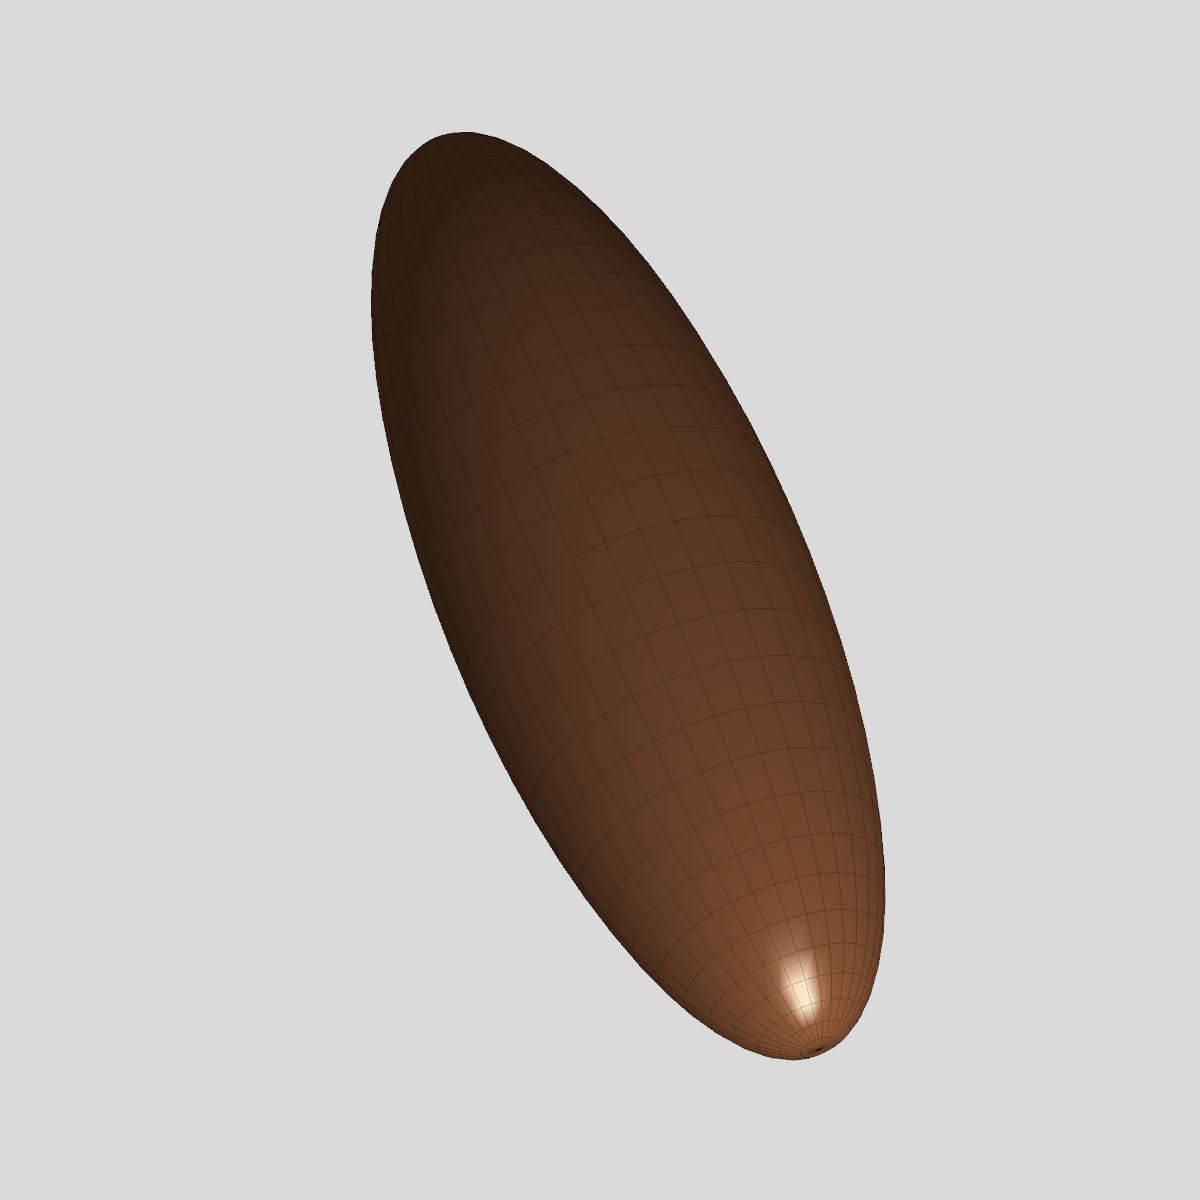

% Illustrative
ev = [1 1 3];

% Render an ellipsoid with specified eigenvalues
[px py pz] = ellipsoid(1,1,1,ev(1),ev(2),ev(3),32);
surf(px,pz,py,repmat(256,size(px)),'EdgeAlpha',0.2,'EdgeColor',[0 0 0]);

% Ligt it and show it
camlight; 
lighting phong; material shiny; 
set(gca, 'Projection', 'perspective');
axis equal vis3d off; colormap(copper);
view(-20,60);
set(gcf,'Position',[400 30 600 600]);
whitebg(gcf,'white')

## Add an axis

axLen = ev.*2+.2; hold on; 
line([0;axLen(1)],[0;0],[0;0],'Color','r','LineWidth',2); 
line([0;0],[0;axLen(2)],[0;0],'Color','g','LineWidth',2); 
line([0;0],[0;0],[0;axLen(3)],'Color','b','LineWidth',2); 
hold off;

## Save it as a png file in the current directory

mrUtilPrintFigure('ellipsoid.png',gcf,0);
disp('Saved as ellipsoid.png in current dir');

## Build a diffusion tensor from a simple 6-direction encoding scheme.

By using 6 directions, we guarantee that the tensor will perfectly fit the data. (But the code below will work for any number of directions.)

bvecs = [1,1,0; 1,0,1; 0,1,1; -1,1,0; -1,0,1; 0,-1,1];

% Make sure bvecs are unit vectors
bvecs = bvecs./repmat(sqrt(sum(bvecs.^2,2)),1,3);
adc = [1 2 3 1 2 1];

% Solve for the diffusion tensor D:
m = [bvecs(:,1).^2 bvecs(:,2).^2 bvecs(:,3).^2 2*bvecs(:,1).*bvecs(:,2) 2*bvecs(:,1).*bvecs(:,3) 2*bvecs(:,2).*bvecs(:,3)];
coef = pinv(m)*adc';
D = [coef(1) coef(4) coef(5); coef(4) coef(2) coef(6); coef(5) coef(6) coef(3)]; 

% Confirm that D can accurately predict the ADC data
pAdc = zeros(1,length(adc));
for ii=1:length(adc)
  pAdc(ii) = bvecs(ii,:)*D*bvecs(ii,:)';
end
fprintf('max diff between ADC and predicetd ADC: %g\n',max(abs(pAdc-adc)));

max diff between ADC and predicetd ADC: 1.11022e-15


## Compute the surfaces

[x,y,z] = sphere(32);
sz = size(x);
u = [x(:), y(:), z(:)];

[vec,val] = eig(D);

dirADC = diag(adc)*bvecs;
% The probability that a spin at the origin will move to position v at time
% t given diffusion tensor D is:
% p_x = 1./sqrt(det(D)*(4*pi*t).^3) * exp(-(v*D-1*v')./(4*t));
 
% Using the diffusion tensor to transform the unit sphere coords
% produces an ellipsoid, even if there are non-zero off-diagonals in D.
% clear e
e{1} = u*D;

% We use D to predict ADC values for each direction.
% 
% Scaling the unit sphere points by the predicted ADC produces a
% peanut. This is the proper way to predicted ADC profile. This is clear
% when we render the surface along with the original ADC values.
sphAdc = zeros(1,size(u,1));
for ii=1:size(u,1)
    sphAdc(ii) = u(ii,:)*D*u(ii,:)';
end
% scale the unit vectors by the predicted ADC for each vector
e{2} = diag(sphAdc)*u;

% Using the eigenvalue decomposition also produces an ellipsoid. This
% ellipsoid DOES NOT represent the predicted ADC profile. Rather, it
% represents the RMS diffusion distance of spins that began at the center
% of the voxel. Note that this surface will accurately predict the ADC
% values that happen to fall exactly on one of the three axes of the
% ellipsoid. (They'd better, since the eigenvalues are taken as the ADC's
% along the three axes of the ellipsoid.) This surface does not, however,
% predict the ADC profile.
e{3} = u*sqrt(2*val)*vec';

## Render the surfaces

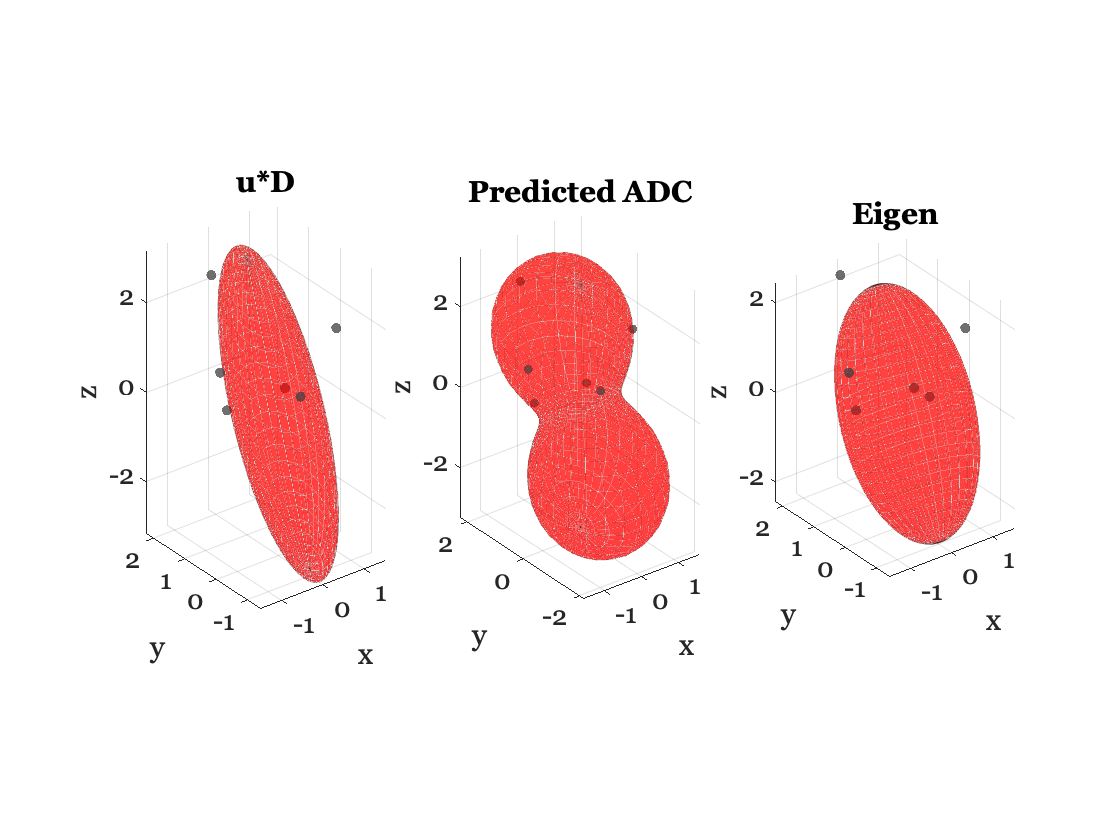

figure;
titles = {'u*D','Predicted ADC','Eigen'};
cmap = [autumn(255); [.25 .25 .25]];
for ii=1:length(e)
    subplot(1,length(e),ii);
    x = reshape(e{ii}(:,1),sz); y = reshape(e{ii}(:,2),sz); z = reshape(e{ii}(:,3),sz);
    surf(x,y,z,'EdgeAlpha',0.1);
    hold on;
    for jj=1:length(adc)
        [px py pz] = ellipsoid(dirADC(jj,1),dirADC(jj,2),dirADC(jj,3),.1,.1,.1,8);
        surf(px,py,pz,repmat(256,size(pz)),'EdgeAlpha',0);
    end
    hold off;
    axis equal vis3d; colormap(cmap); alpha 0.5;
    title(titles{ii});
    xlabel('x');ylabel('y');zlabel('z');
end

## Drawing the ellipsoid that correspond with the ADC measurements (Tony)

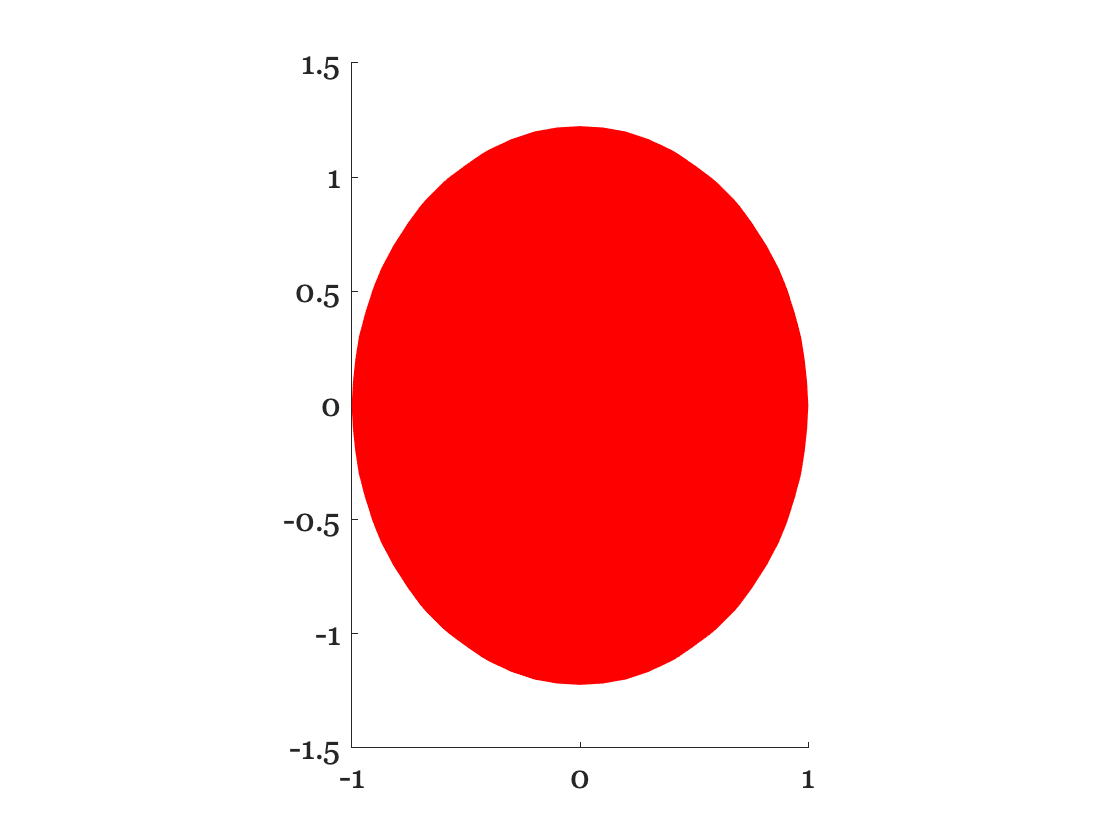

[xmesh, ymesh, zmesh] = meshgrid(-3:0.1:3,-3:0.1:3,-3:0.1:3);

% Make the ellipsoid mesh
vmesh = coef(1)*xmesh.^2 + coef(2)*ymesh.^2 + ...
    coef(3)*zmesh.^2 + coef(4)*2*xmesh.*ymesh + coef(5)*2*xmesh.*zmesh + coef(6)*2*ymesh.*zmesh;

figure; 
p = patch(isosurface(xmesh,ymesh,zmesh,vmesh,1));
isonormals(xmesh,ymesh,zmesh,vmesh,p)
set(p,'FaceColor','red','EdgeColor','none','EdgeAlpha',0.1);%
daspect([1 1 1])
hold on;

## Draw the ellipsoid that corresponds with the covariance matrix of the

gaussian pdf on the water molecule movement

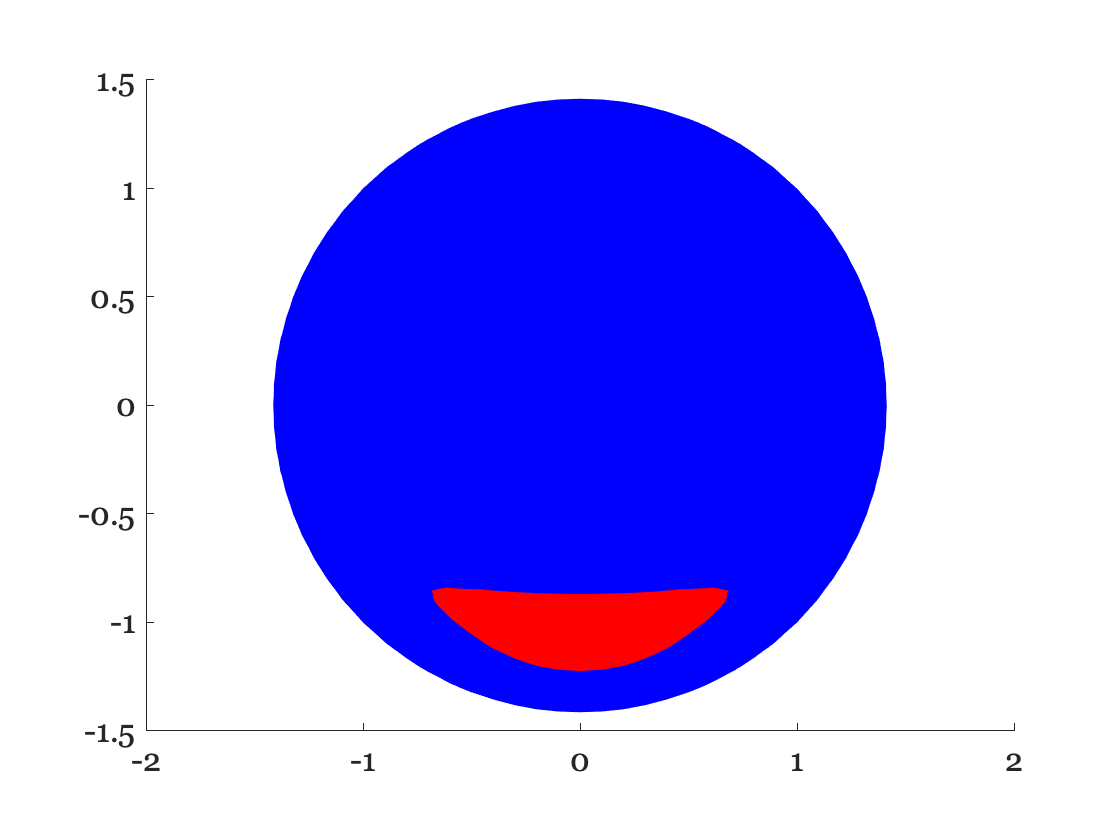

[U S V] = svd(D);
Dinv = U*diag(1./diag(2*S))*V';
coef_inv = [Dinv(1,1) Dinv(2,2) Dinv(3,3) Dinv(1,2) Dinv(1,3) Dinv(2,3)];
vmesh = coef_inv(1)*xmesh.^2 + coef_inv(2)*ymesh.^2 + coef_inv(3)*zmesh.^2 + coef_inv(4)*2*xmesh.*ymesh + coef_inv(5)*2*xmesh.*zmesh + coef_inv(6)*2*ymesh.*zmesh;
p = patch(isosurface(xmesh,ymesh,zmesh,vmesh,1));
isonormals(xmesh,ymesh,zmesh,vmesh,p)
set(p,'FaceColor','blue','EdgeColor','none','EdgeAlpha',0.1);%
daspect([1 1 1])

## Putting the ADC measurement points onto the ellipsoid

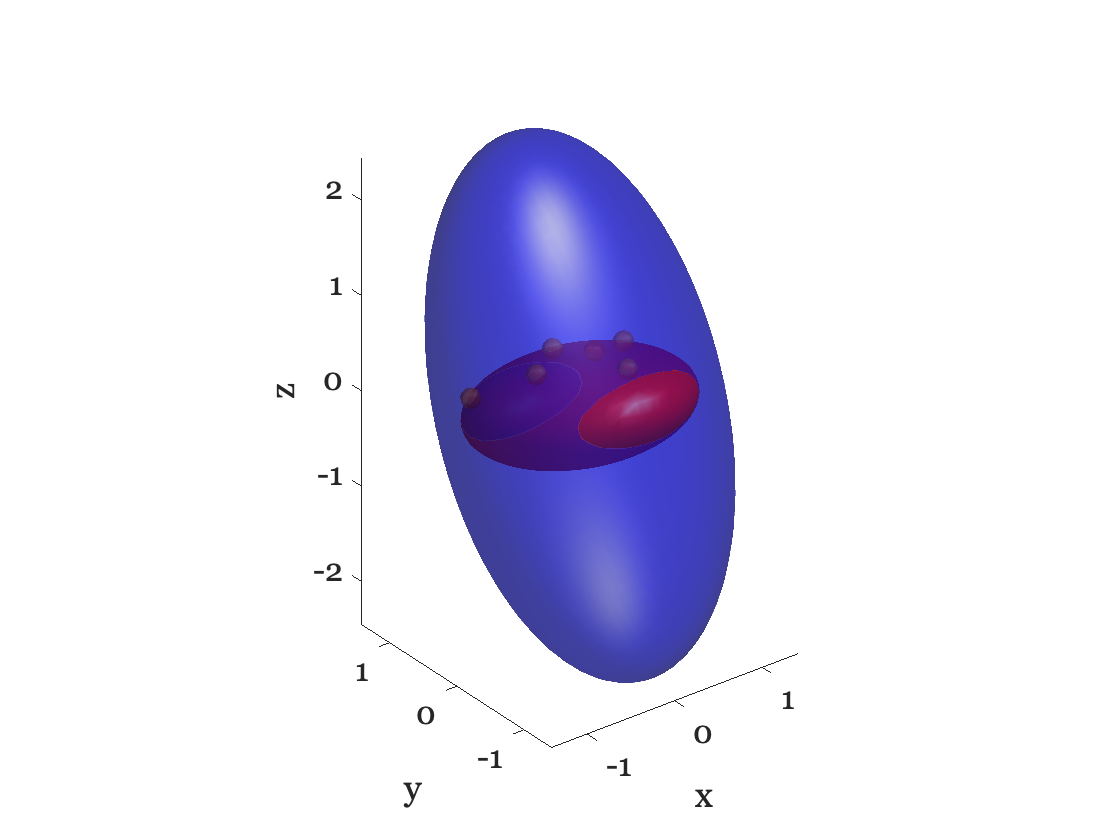

dirADC = diag(1./sqrt(adc))*bvecs;
for jj=1:length(adc)
    [px py pz] = ellipsoid(dirADC(jj,1),dirADC(jj,2),dirADC(jj,3),.1,.1,.1,8);
    surf(px,py,pz,repmat(256,size(pz)),'EdgeAlpha',0);
end

hold off;
view(3);
camlight 
lighting gouraud
axis equal vis3d; colormap(cmap); alpha 0.5;
xlabel('x');ylabel('y');zlabel('z');

## Set up multiple contributors

% Illustrative
[x,y,z] = sphere(16);
grad_dirs = [x(:),y(:),z(:)];
x(1) = 0.3;
x(2) = .3*10^9;

% Make two different orientations
fibredir = [1,1,0]';
fibredir = fibredir/norm(fibredir);
ev1 = [1 .3 .3];
[u s v] = svd(fibredir);
Q1 = u*diag((1./ev1).^2)*u';

% Make two different orientations
fibredir = [0,1,1]';
fibredir = fibredir/norm(fibredir);
[u s v] = svd(fibredir);
Q2 = u*diag((1./ev1).^2)*u';

## Plot the ADC values for Q1

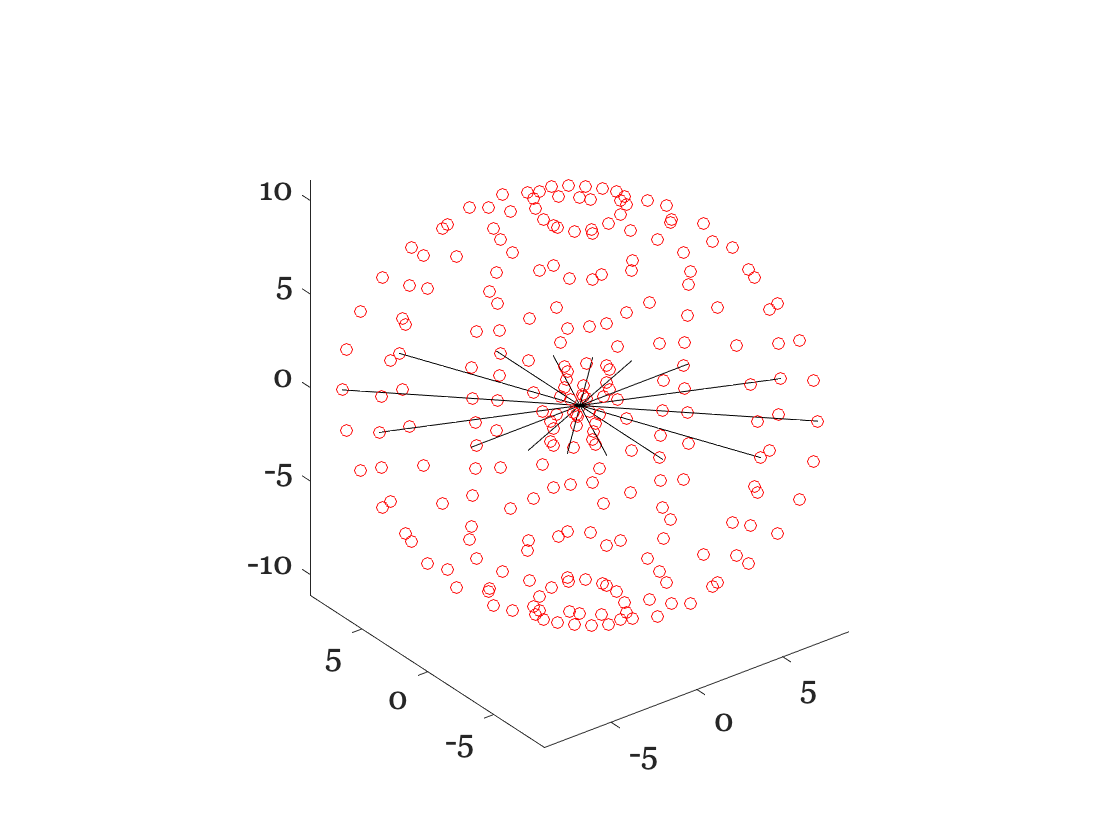

% Given a tensor, Q1, we calculate the ADC in a particular direction this
% way:
s = grad_dirs*Q1*grad_dirs';
s = diag(s);

% To show the size of the ADC in the gradient direction, we plot the size
grad_dirs_s = zeros(size(grad_dirs));
for ii=1:size(grad_dirs,1)
    grad_dirs_s(ii,:) = grad_dirs(ii,:)*s(ii);
end
grad_dirs_s2 = [grad_dirs_s; -grad_dirs_s];

figure; 
plot3(grad_dirs_s2(:,1),grad_dirs_s2(:,2),grad_dirs_s2(:,3),'o')
axis equal

patch(grad_dirs_s2(:,1),grad_dirs_s2(:,2),grad_dirs_s2(:,3))

## We plot the values on representing the diffusion distance this way

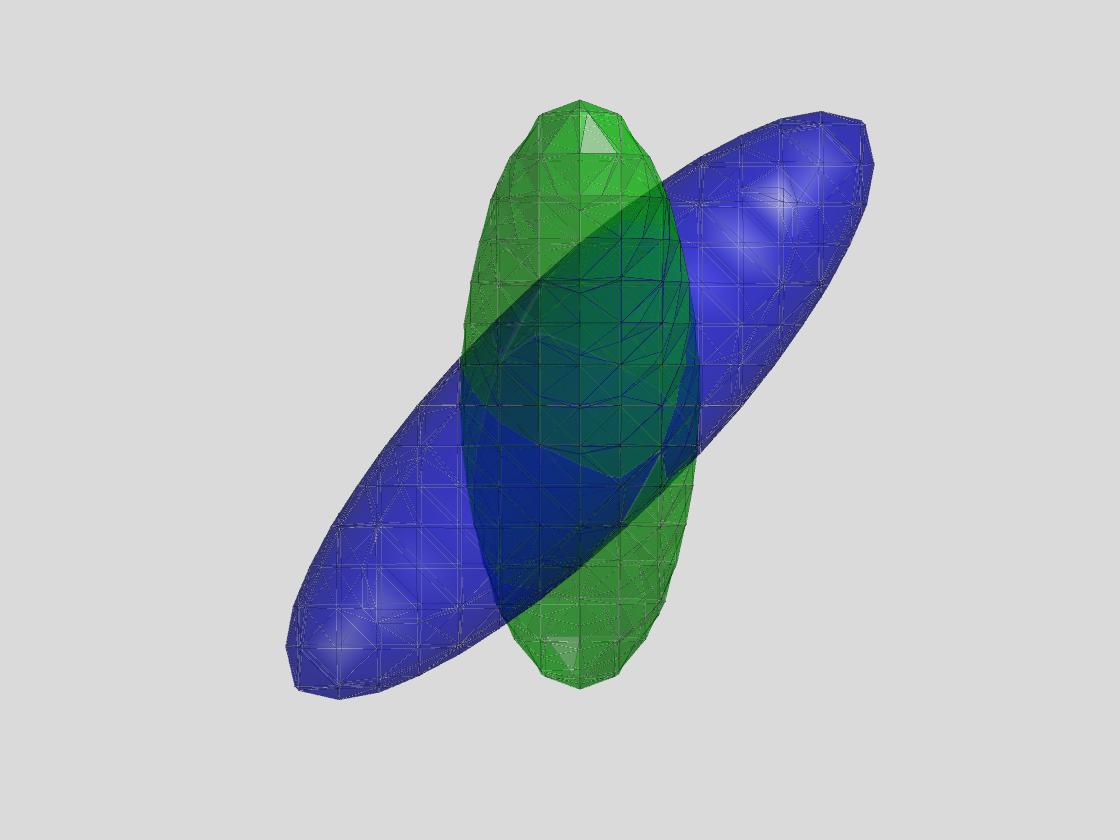

% These are the 3D points that solve 1 = grad_dirs' * Q1 * grad_dirs
[xmesh, ymesh, zmesh] = meshgrid(-3:0.1:3,-3:0.1:3,-3:0.1:3);
% D = [coef(1) coef(4) coef(5); coef(4) coef(2) coef(6); coef(5) coef(6) coef(3)]; 
coef1 = [Q1(1,1) Q1(2,2) Q1(3,3) Q1(1,2) Q1(1,3) Q1(2,3)];
vmesh1 = coef1(1)*xmesh.^2 + coef1(2)*ymesh.^2 + ...
    coef1(3)*zmesh.^2 + coef1(4)*2*xmesh.*ymesh + coef1(5)*2*xmesh.*zmesh + coef1(6)*2*ymesh.*zmesh;

coef2 = [Q2(1,1) Q2(2,2) Q2(3,3) Q2(1,2) Q2(1,3) Q2(2,3)];
vmesh2 = coef2(1)*xmesh.^2 + coef2(2)*ymesh.^2 + ...
    coef2(3)*zmesh.^2 + coef2(4)*2*xmesh.*ymesh + coef2(5)*2*xmesh.*zmesh + coef2(6)*2*ymesh.*zmesh;


figure; 
p = patch(isosurface(xmesh,ymesh,zmesh,vmesh1,1));
isonormals(xmesh,ymesh,zmesh,vmesh1,p)
% daspect([1 1 1])
colormap(jet);
%set(p,'FaceColor',[0 .3 .6],'EdgeAlpha',0.2,'EdgeColor',[0 0 0]);
set(p,'FaceColor','b','EdgeAlpha',0.2,'EdgeColor',[0 0 0]);
daspect([1 1 1])

camlight; 
lighting phong; 
material shiny; 

set(gca, 'Projection', 'perspective');
axis off
whitebg(gcf,'white')

p = patch(isosurface(xmesh,ymesh,zmesh,vmesh2,1));
isonormals(xmesh,ymesh,zmesh,vmesh2,p)
daspect([1 1 1])
set(p,'FaceColor','g','EdgeAlpha',0.2,'EdgeColor',[0 0 0]);
alpha 0.5
axis off
grid on

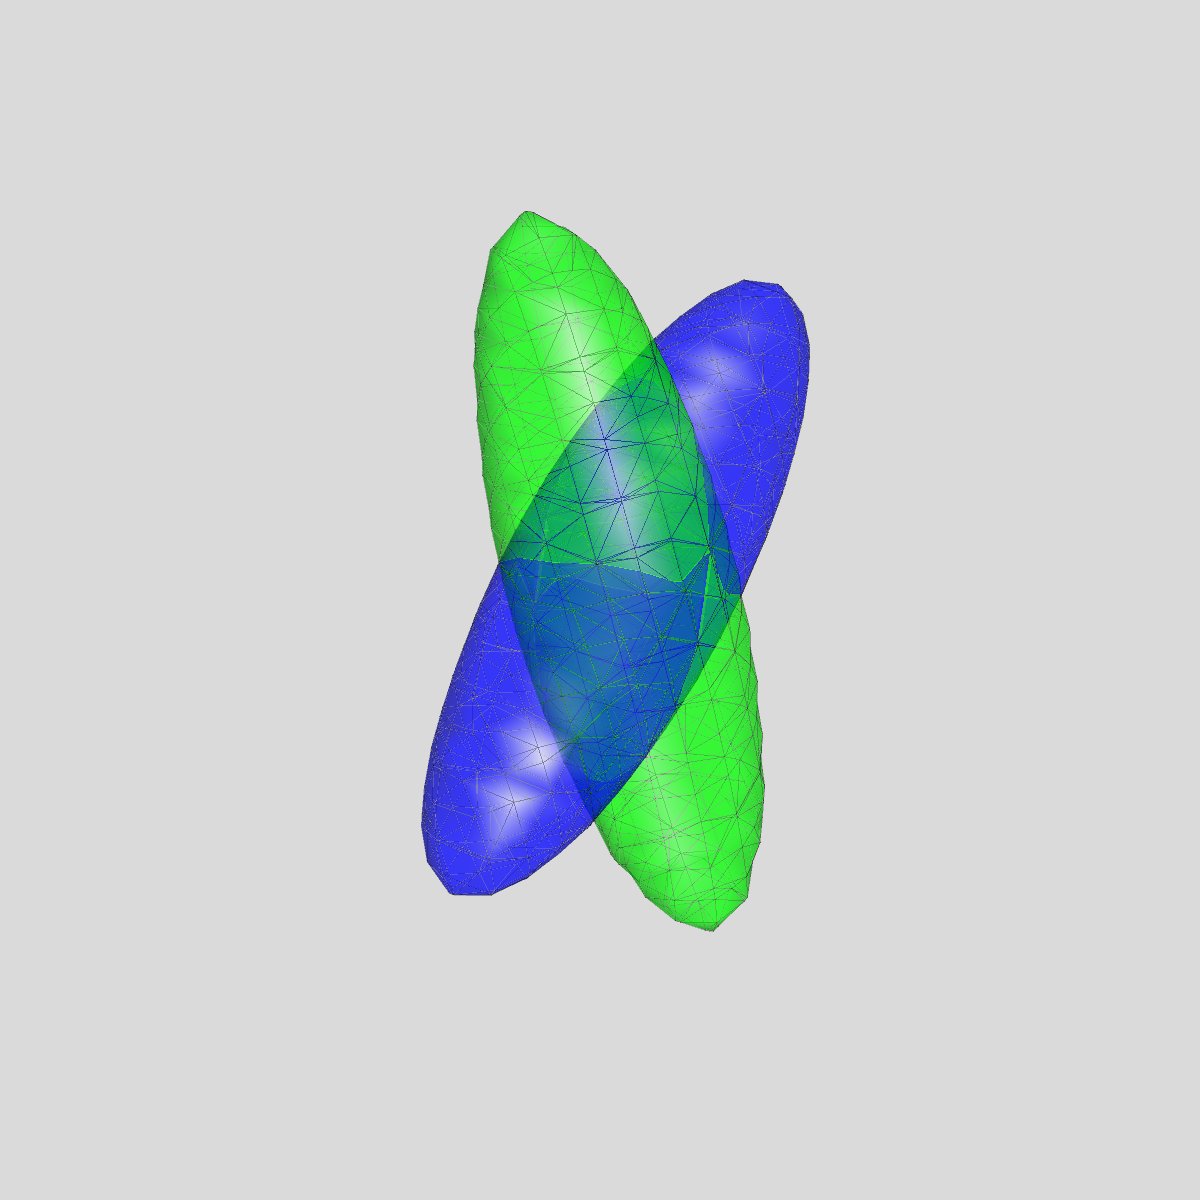

view(3);
camlight 
lighting gouraud
axis equal vis3d; 
colormap(cmap); 
alpha 0.5;
xlabel('x');ylabel('y');zlabel('z');

camlight; 
lighting gouraud; material shiny; 
set(gca, 'Projection', 'perspective');
axis equal vis3d on; colormap(copper);
whitebg(gcf,'white')
grid on

% dirADC = diag(1./sqrt(adc))*bvecs;
% for jj=1:length(adc)
%     [px py pz] = ellipsoid(dirADC(jj,1),dirADC(jj,2),dirADC(jj,3),.1,.1,.1,8);
%     surf(px,py,pz,repmat(256,size(pz)),'EdgeAlpha',0);
% end




f=x(1);
dPar=x(2);
dPerp=dPar*(1-f);

% Radial wavenumbers
% GAMMA = 2.675987E8;
% modQ = GAMMA*smalldel.*G;
% modQ_Sq = modQ.^2;

modQ_Sq = 1;

% Synthesize measurements from model
%l_q=length(grad_dirs);
cosTheta = grad_dirs*fibredir(:);
cosThetaSq = cosTheta.^2;
% difftime = (delta-smalldel/3);
difftime = 1;
E = exp(-difftime.*modQ_Sq.*((dPar - dPerp)*cosThetaSq + dPerp));

% Ligt it and show it
camlight; 
lighting phong; material shiny; 
set(gca, 'Projection', 'perspective');
axis equal vis3d off; colormap(copper);
view(-20,60);
set(gcf,'Position',[400 30 600 600]);
whitebg(gcf,'white')